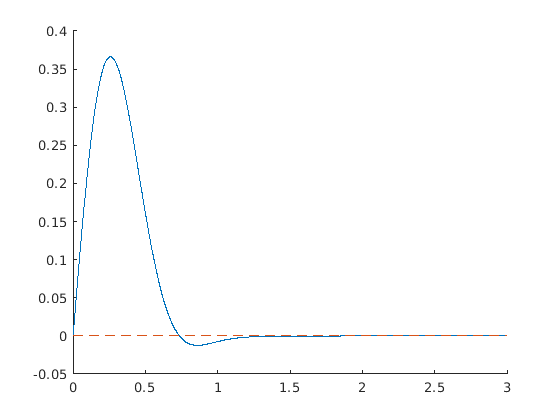

clf

r = 2.5;  % Meta-parameters
D = 1;
f = @(k) k.*exp(- D*abs(k).^r);


% Plot original function
x_max = 5;  % Parameters
x_points = 10001;

xs = linspace(0, x_max, x_points);  % Plot
%plot(xs, f(xs))


% Fourier transform
freq_max = 1000;
freq_min = 0.001;
eval_points = 0:(1/freq_max):(1/freq_min);
Fs = - imag(fft(f(eval_points)))/freq_max;


% Plot Fourier transform
k_max = 3; %0.5*freq_max;  % Parameters

ks = 0:freq_min:freq_max;  % Plot
hold on
plot(ks, Fs)
plot(ks, zeros(size(ks)), '--')
hold off
xlim([0, k_max])